Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 9600, Timeout=2);
configureTerminator(STM32_ser,"CR");

Richiedo il buffer tramite char 'e'

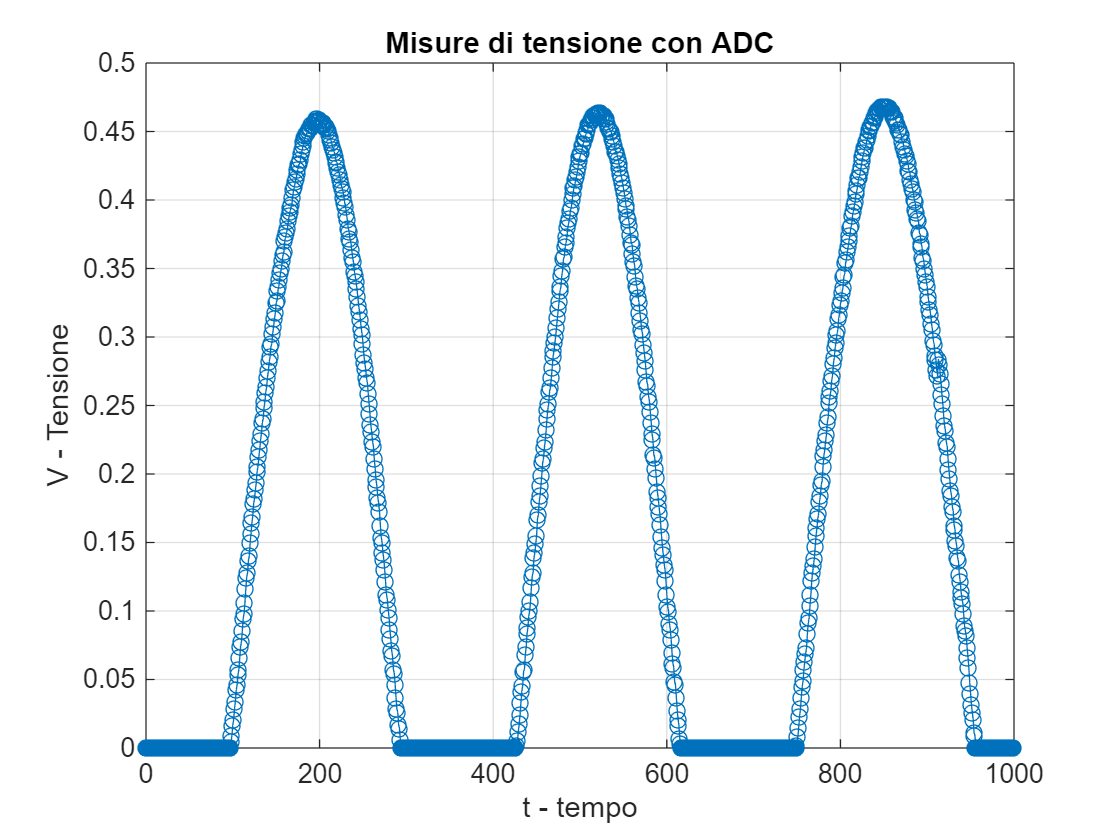

figure(1)
% fprintf('Valore Medio: %f°C',mean(vettore));
% fprintf('Deviazione standard : %f',std(vettore));


while 1
    STM32_ser.flush;
    clear vettore;
    STM32_ser.write('e','char');
    vettore=read(STM32_ser,1000,'uint16');

    for i=1:length(vettore)
       vettore(i) = vettore(i)/cast(intmax('uint16'), 'double');
    end
    
    plot(vettore(1:1000), '-o');
    title('Misure di tensione con ADC');
    ylabel("V - Tensione");
    xlabel('t - tempo');
    box on;
    grid on
end